# Parameter Effects - Physiological Regime

AUTHOR: Kambadur Ananthamurthy

MAIN PROBLEM STATEMENT: Can we use concordance to make better predictions about detecting Time Cells?

DETAILS: 333 uniquely tagged synthetic datasets were analysed on the basis of a variety of numerical procedures (8 algorithms). Subsequently, these scores were used with either Bootstrapping or Otsu's Threshold based methods to classify cells.

Using the configuration for each of the 333 synthetic datasets we split the data based on "Hit Trial Ratio", "Event Width", "Imprecision", and "Noise", and compare the predictions of each of the 8 algorithms against ground truth.

close all
clear

tic

input.nCells = 135;
input.nAlgos = 8;
input.nMethods = 6;

workingOnServer = 1; %Only to select the batch for datasets

if workingOnServer == 1 %Bebinca
    % Synthetic Dataset Details
    input.gDate = 20210824; %generation date
    input.gRun = 1; %generation run number
    input.nDatasets = 333;
    
    % Consolidated Analysis Details
    input.cDate = 20210918; %consolidation date
    input.cRun = 1; %consolidation run number
    
elseif workingOnServer == 2 %Adama
    % Synthetic Dataset Details
    input.gDate = 20210903; %generation date
    input.gRun = 1; %generation run number
    input.nDatasets = 333;
    
    % Consolidated Analysis Details
    input.cDate = 20210911; %consolidation date
    input.cRun = 1; %consolidation run number
end

workingOnServer = 0; %Current
diaryOn         = 0;


% Directory config

if workingOnServer == 1
    HOME_DIR = '/home/bhalla/ananthamurthy/';
    saveDirec = strcat(HOME_DIR, 'Work/Analysis/Imaging/');
elseif workingOnServer == 2
    HOME_DIR = '/home/ananth/Documents/';
    HOME_DIR2 = '/home/ananth/Desktop/';
    saveDirec = strcat(HOME_DIR2, 'Work/Analysis/Imaging/');
else
    HOME_DIR = '/Users/ananth/Documents/';
    HOME_DIR2 = '/Users/ananth/Desktop/';
    saveDirec = strcat(HOME_DIR2, 'Work/Analysis/Imaging/');
end
%Additinal search paths
addpath(genpath(strcat(HOME_DIR, 'rho-matlab/CustomFunctions')))
addpath(genpath(strcat(HOME_DIR, 'rho-matlab/localCopies')))
make_db

saveFolder = strcat(saveDirec, db.mouseName, '/', db.date, '/');

if diaryOn
    if workingOnServer == 1
        diary (strcat(HOME_DIR, '/logs/benchmarksDiary'))
    else
        diary (strcat(HOME_DIR2, '/logs/benchmarksDiary_', num2str(gDate), '_', num2str(gRun)))
    end
    diary on
end

% Operations
plotRefQ = 1;
plotAnalysedQs = 1;
plotDatasetCheck = 0;

% Load Synthetic Data
disp('Loading synthetic datasets ...')

Loading synthetic datasets ...


synthDataFilePath = sprintf('%s/synthDATA_%i_gRun%i_batch_%i.mat', ...
    saveFolder, ...
    input.gDate, ...
    input.gRun, ...
    input.nDatasets);
load(synthDataFilePath)
disp('... done!')

... done!



% Load Analysis Results
disp('Loading analysis results ...')

Loading analysis results ...


analysisFilePath = sprintf('%s/synthDATA_Analysis_%i_cRun%i_cData.mat', ...
    saveFolder, ...
    input.cDate, ...
    input.cRun);
load(analysisFilePath)
disp('... done!')

... done!



input.removeNaNs = 0;
input.saveFolder = saveFolder;

%Labels
algoLabels = {'A-Boot', 'B-Boot', 'C-Boot', 'C-Otsu', 'D-Otsu', 'E-Otsu', 'F-Boot', 'F-Otsu'};
metricLabels = {'Recall', 'Precision', 'F1 Score'};
methodLabels = {'R2B', 'TI', 'Peak AUC/Std', 'PCA', 'SVM', 'Param. Eqs.'};
methodLabels2 = {'A', 'B', 'C', 'D', 'E', 'F'};
legends1 = {'TPR', 'FPR', 'TNR', 'FNR'};

figureDetails = compileFigureDetails(16, 2, 5, 0.2, 'inferno'); %(fontSize, lineWidth, markerSize, transparency, colorMap)
%Extra colormap options: inferno/plasma/viridis/magma

## Physiological Regime - Datasets 298 to 333

For this, consult setupSyntheticDataParams4.m (or configSynth.m)

There are N=3 randomizations per tag.

## Dataset indices

nSets = 3;

iNoise1 = (298:300); %low
iNoise2 = (301:303); %medium
iNoise3 = (304:306); %high

iEW1 = (307:309); %small
iEW2 = (310:312); %medium
iEW3 = (313:315); %large

iImp1 = (316:318); %low
iImp2 = (319:321); %medium
iImp3 = (322:324); %high

iHTR1 = (325:327); %low
iHTR2 = (328:330); %medium
iHTR3 = (331:333); %high

## Noise - Predcitions

mainBarplotTitle = 'Noise - ';
[Y1, X1] = developConfusionMatrix4Effects(input, sdo_batch, cData, iNoise1);

Creating Confusion Matrix ...
... done!


[Y2, X2] = developConfusionMatrix4Effects(input, sdo_batch, cData, iNoise2);

Creating Confusion Matrix ...
... done!


[Y3, X3] = developConfusionMatrix4Effects(input, sdo_batch, cData, iNoise3);

Creating Confusion Matrix ...
... done!


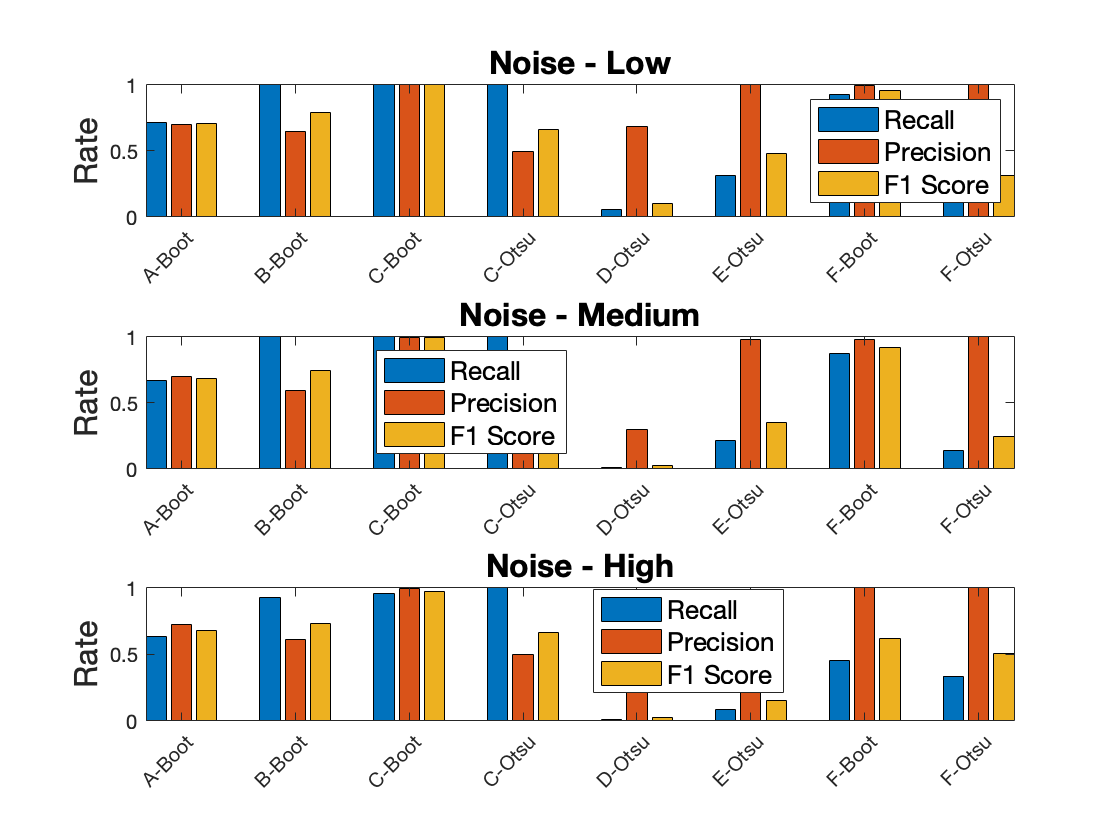

fig1 = figure(1);
clf
%set(fig1, 'Position', [300, 300, 800, 1200])
for set = 1:nSets
    if set == 1
        X = X1;
        Y = Y1;
    elseif set == 2
        X = X2;
        Y = Y2;
    elseif set == 3
        X = X3;
        Y = Y3;
    end
    
    [results1, results2, results3] = compareAgainstTruth(X, Y, input);
    
    subplot(3, 1, set)
    b = bar(results3);
    xlim([0, 2])
    axis tight
    % title(sprintf('Performance Evaluation (N=%i)', input.nDatasets), ...
    %     'FontSize', figureDetails.fontSize, ...
    %     'FontWeight', 'bold')
    if set == 1
        title([mainBarplotTitle, 'Low'], ...
            'FontSize', figureDetails.fontSize, ...
            'FontWeight', 'bold')
    elseif set == 2
        title([mainBarplotTitle, 'Medium'], ...
            'FontSize', figureDetails.fontSize, ...
            'FontWeight', 'bold')
    elseif set == 3
        title([mainBarplotTitle, 'High'], ...
            'FontSize', figureDetails.fontSize, ...
            'FontWeight', 'bold')
    end
    ylabel('Rate', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xticklabels(algoLabels)
    xtickangle(45)
    %set(gca,'xtick',[])
    lgd = legend(metricLabels, ...
        'Location', 'best');
    lgd.FontSize = figureDetails.fontSize-3;
    %set(gca, 'FontSize', figureDetails.fontSize)
end

## Event Widths - Predictions

mainBarplotTitle = 'Event Widths - ';
[Y1, X1] = developConfusionMatrix4Effects(input, sdo_batch, cData, iEW1);

Creating Confusion Matrix ...
... done!


[Y2, X2] = developConfusionMatrix4Effects(input, sdo_batch, cData, iEW2);

Creating Confusion Matrix ...
... done!


[Y3, X3] = developConfusionMatrix4Effects(input, sdo_batch, cData, iEW3);

Creating Confusion Matrix ...
... done!


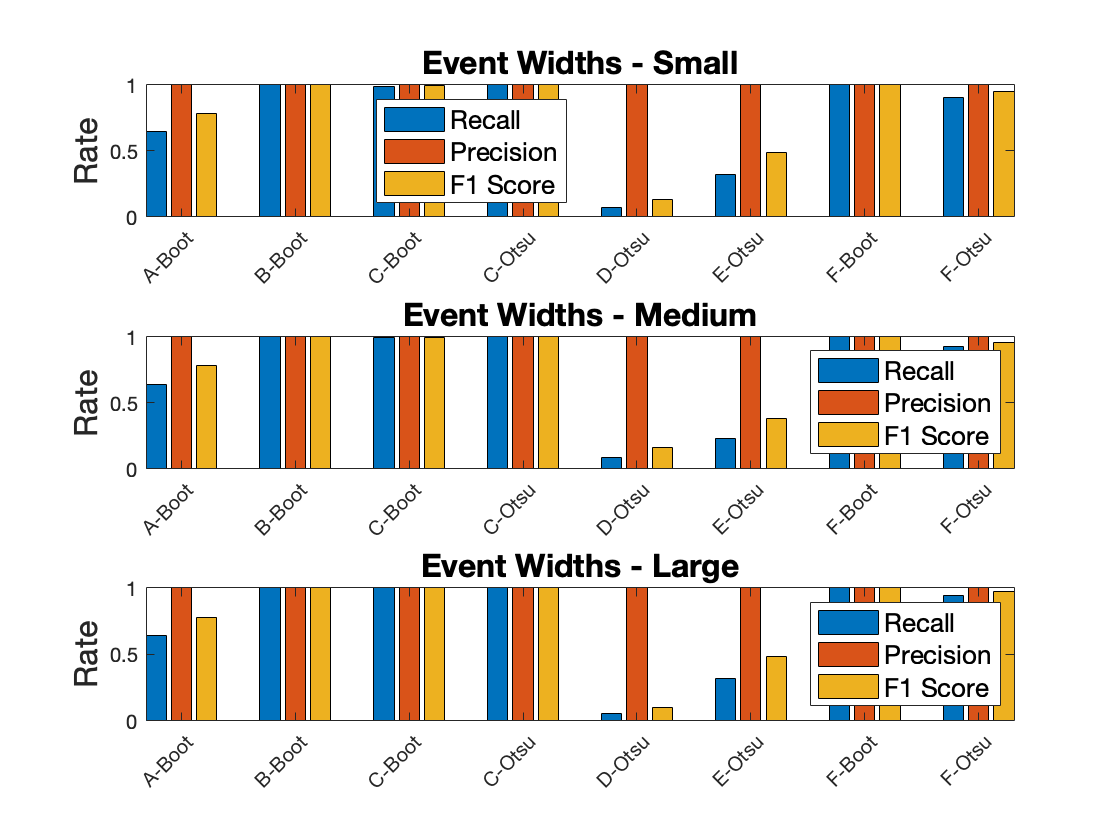


fig2 = figure(2);
clf
%set(fig2, 'Position', [300, 300, 800, 1200])
for set = 1:nSets
    if set == 1
        X = X1;
        Y = Y1;
    elseif set == 2
        X = X2;
        Y = Y2;
    elseif set == 3
        X = X3;
        Y = Y3;
    end
    
    [results1, results2, results3] = compareAgainstTruth(X, Y, input);
    
    subplot(3, 1, set)
    b = bar(results3);
    xlim([0, 2])
    axis tight
    % title(sprintf('Performance Evaluation (N=%i)', input.nDatasets), ...
    %     'FontSize', figureDetails.fontSize, ...
    %     'FontWeight', 'bold')
    if set == 1
        title([mainBarplotTitle, 'Small'], ...
            'FontSize', figureDetails.fontSize, ...
            'FontWeight', 'bold')
    elseif set == 2
        title([mainBarplotTitle, 'Medium'], ...
            'FontSize', figureDetails.fontSize, ...
            'FontWeight', 'bold')
    elseif set == 3
        title([mainBarplotTitle, 'Large'], ...
            'FontSize', figureDetails.fontSize, ...
            'FontWeight', 'bold')
    end
    
    ylabel('Rate', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xticklabels(algoLabels)
    xtickangle(45)
    %set(gca,'xtick',[])
    lgd = legend(metricLabels, ...
        'Location', 'best');
    lgd.FontSize = figureDetails.fontSize-3;
    %set(gca, 'FontSize', figureDetails.fontSize)

end

## Imprecision - Predictions

mainBarplotTitle = 'Imprecision - ';
[Y1, X1] = developConfusionMatrix4Effects(input, sdo_batch, cData, iImp1);

Creating Confusion Matrix ...
... done!


[Y2, X2] = developConfusionMatrix4Effects(input, sdo_batch, cData, iImp2);

Creating Confusion Matrix ...
... done!


[Y3, X3] = developConfusionMatrix4Effects(input, sdo_batch, cData, iImp3);

Creating Confusion Matrix ...
... done!


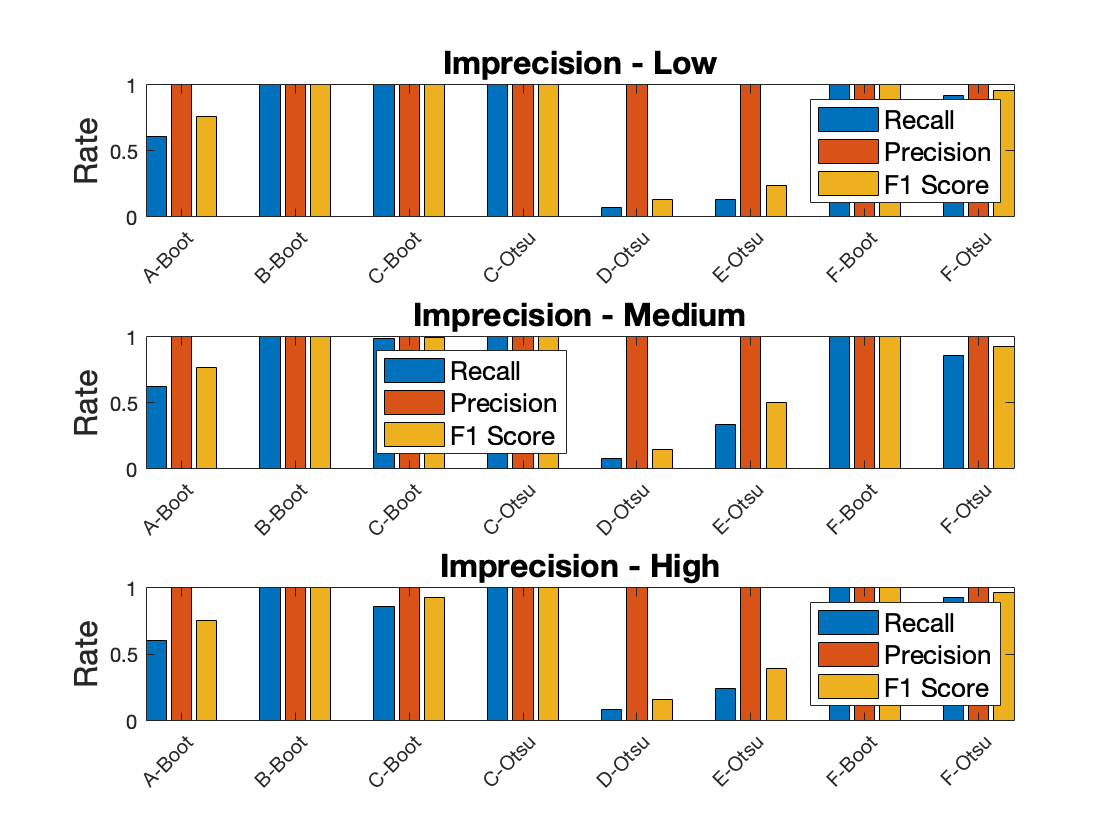


fig3 = figure(3);
clf
%set(fig3, 'Position', [300, 300, 800, 1200])
for set = 1:nSets
    if set == 1
        X = X1;
        Y = Y1;
    elseif set == 2
        X = X2;
        Y = Y2;
    elseif set == 3
        X = X3;
        Y = Y3;
    end
    
    [results1, results2, results3] = compareAgainstTruth(X, Y, input);
    
    subplot(3, 1, set)
    b = bar(results3);
    xlim([0, 2])
    axis tight
    % title(sprintf('Performance Evaluation (N=%i)', input.nDatasets), ...
    %     'FontSize', figureDetails.fontSize, ...
    %     'FontWeight', 'bold')
    if set == 1
        title([mainBarplotTitle, 'Low'], ...
            'FontSize', figureDetails.fontSize, ...
            'FontWeight', 'bold')
    elseif set == 2
        title([mainBarplotTitle, 'Medium'], ...
            'FontSize', figureDetails.fontSize, ...
            'FontWeight', 'bold')
    elseif set == 3
        title([mainBarplotTitle, 'High'], ...
            'FontSize', figureDetails.fontSize, ...
            'FontWeight', 'bold')
    end
    
    ylabel('Rate', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xticklabels(algoLabels)
    xtickangle(45)
    %set(gca,'xtick',[])
    lgd = legend(metricLabels, ...
        'Location', 'best');
    lgd.FontSize = figureDetails.fontSize-3;
    %set(gca, 'FontSize', figureDetails.fontSize)

end

## Hit Trial Ratio - Predictions

mainBarplotTitle = 'Hit Trial Ratio - ';
[Y1, X1] = developConfusionMatrix4Effects(input, sdo_batch, cData, iHTR1);

Creating Confusion Matrix ...
... done!


[Y2, X2] = developConfusionMatrix4Effects(input, sdo_batch, cData, iHTR2);

Creating Confusion Matrix ...
... done!


[Y3, X3] = developConfusionMatrix4Effects(input, sdo_batch, cData, iHTR3);

Creating Confusion Matrix ...
... done!


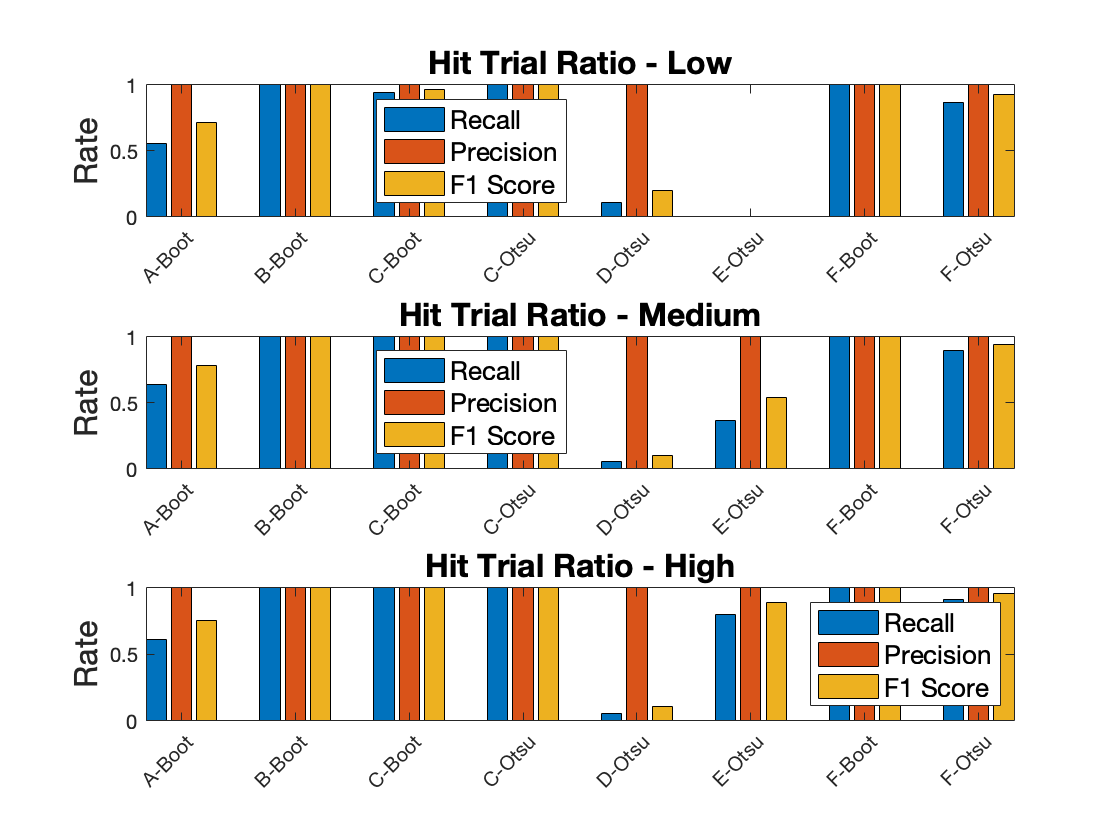


fig4 = figure(4);
clf
%set(fig4, 'Position', [300, 300, 800, 1200])
for set = 1:nSets
    if set == 1
        X = X1;
        Y = Y1;
    elseif set == 2
        X = X2;
        Y = Y2;
    elseif set == 3
        X = X3;
        Y = Y3;
    end
    
    [results1, results2, results3] = compareAgainstTruth(X, Y, input);

    subplot(3, 1, set)
    b = bar(results3);
    xlim([0, 2])
    axis tight
    % title(sprintf('Performance Evaluation (N=%i)', input.nDatasets), ...
    %     'FontSize', figureDetails.fontSize, ...
    %     'FontWeight', 'bold')
    if set == 1
        title([mainBarplotTitle, 'Low'], ...
            'FontSize', figureDetails.fontSize, ...
            'FontWeight', 'bold')
    elseif set == 2
        title([mainBarplotTitle, 'Medium'], ...
            'FontSize', figureDetails.fontSize, ...
            'FontWeight', 'bold')
    elseif set == 3
        title([mainBarplotTitle, 'High'], ...
            'FontSize', figureDetails.fontSize, ...
            'FontWeight', 'bold')
    end
    
    ylabel('Rate', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xticklabels(algoLabels)
    xtickangle(45)
    %set(gca,'xtick',[])
    lgd = legend(metricLabels, ...
        'Location', 'best');
    lgd.FontSize = figureDetails.fontSize-3;
    %set(gca, 'FontSize', figureDetails.fontSize)

end

## Line Plots - Noise

fig5 = figure(5);
clf
set(fig5, 'Position', [100, 100, 800, 800])

## Noise - Scores

[response1, predictor1] = getTheTable4Effects(sdo_batch, cData, input, iNoise1);

Creating Look Up Table ...
... done!


[response2, predictor2] = getTheTable4Effects(sdo_batch, cData, input, iNoise2);

Creating Look Up Table ...
... done!


[response3, predictor3] = getTheTable4Effects(sdo_batch, cData, input, iNoise3);

Creating Look Up Table ...
... done!



% Z-scores
Z1 = zscore(predictor1);
Z2 = zscore(predictor2);
Z3 = zscore(predictor3);

%Euclidean Distance on actual scores
for method = 1:input.nMethods
    D1(method) = norm(predictor1(:, method) - predictor2(:, method));
    D2(method) = norm(predictor1(:, method) - predictor3(:, method));

    %Euclidean Distance on Z-Scores
    DZ1(method) = norm(Z1(:, method) - Z2(:, method));
    DZ2(method) = norm(Z1(:, method) - Z3(:, method));
end
disp(D1)

   1.0e+03 *

    2.0793    0.3791    0.0664    0.0014    0.0194       NaN



disp(D2)

   1.0e+03 *

    2.0926    0.4485    0.0628    0.0014    0.0211       NaN



disp(DZ1)

   27.8141   23.2715   27.4665   27.3788   22.6890       NaN



disp(DZ2)

   27.8109   28.6882   27.3293   29.0295   28.6176       NaN



## Event Widths - Scores

[response1, predictor1] = getTheTable4Effects(sdo_batch, cData, input, iEW1);

Creating Look Up Table ...
... done!


[response2, predictor2] = getTheTable4Effects(sdo_batch, cData, input, iEW2);

Creating Look Up Table ...
... done!


[response3, predictor3] = getTheTable4Effects(sdo_batch, cData, input, iEW3);

Creating Look Up Table ...
... done!



% Z-scores
Z1 = zscore(predictor1);
Z2 = zscore(predictor2);
Z3 = zscore(predictor3);

%Euclidean Distance on actual scores
for method = 1:input.nMethods
    D1(method) = norm(predictor1(:, method) - predictor2(:, method));
    D2(method) = norm(predictor1(:, method) - predictor3(:, method));

    %Euclidean Distance on Z-Scores
    DZ1(method) = norm(Z1(:, method) - Z2(:, method));
    DZ2(method) = norm(Z1(:, method) - Z3(:, method));
end
disp(D1)

  483.6363   72.6555  112.3992    1.0095   24.5092    3.3994



disp(D2)

  483.5319   71.7296  111.3662    1.3254   75.6516    3.4055



disp(DZ1)

   23.7774   28.8822   28.6390   27.1197   28.3295   28.7916



disp(DZ2)

   24.3809   28.8285   28.6540   28.6062   28.9319   28.7708



## Imprecision - Scores

[response1, predictor1] = getTheTable4Effects(sdo_batch, cData, input, iImp1);

Creating Look Up Table ...
... done!


[response2, predictor2] = getTheTable4Effects(sdo_batch, cData, input, iImp2);

Creating Look Up Table ...
... done!


[response3, predictor3] = getTheTable4Effects(sdo_batch, cData, input, iImp3);

Creating Look Up Table ...
... done!



% Z-scores
Z1 = zscore(predictor1);
Z2 = zscore(predictor2);
Z3 = zscore(predictor3);

%Euclidean Distance on actual scores
for method = 1:input.nMethods
    D1(method) = norm(predictor1(:, method) - predictor2(:, method));
    D2(method) = norm(predictor1(:, method) - predictor3(:, method));

    %Euclidean Distance on Z-Scores
    DZ1(method) = norm(Z1(:, method) - Z2(:, method));
    DZ2(method) = norm(Z1(:, method) - Z3(:, method));
end
disp(D1)

  326.2607   63.0141   99.6988    1.4764   49.8896    2.9530



disp(D2)

  359.2634   64.0123  100.2328    1.2974   87.3245    3.0085



disp(DZ1)

   22.8706   27.6827   27.7763   27.6038   28.9125   26.6890



disp(DZ2)

   26.1649   28.6866   28.6252   25.3443   28.6053   28.2596



## Hit Trial Ratio - Scores

[response1, predictor1] = getTheTable4Effects(sdo_batch, cData, input, iHTR1);

Creating Look Up Table ...
... done!


[response2, predictor2] = getTheTable4Effects(sdo_batch, cData, input, iHTR2);

Creating Look Up Table ...
... done!


[response3, predictor3] = getTheTable4Effects(sdo_batch, cData, input, iHTR3);

Creating Look Up Table ...
... done!



% Z-scores
Z1 = zscore(predictor1);
Z2 = zscore(predictor2);
Z3 = zscore(predictor3);

%Euclidean Distance on actual scores
for method = 1:input.nMethods
    D1(method) = norm(predictor1(:, method) - predictor2(:, method));
    D2(method) = norm(predictor1(:, method) - predictor3(:, method));

    %Euclidean Distance on Z-Scores
    DZ1(method) = norm(Z1(:, method) - Z2(:, method));
    DZ2(method) = norm(Z1(:, method) - Z3(:, method));
end
disp(D1)

  401.6975   69.6075  109.0539    1.0965   53.5626    2.8272



disp(D2)

  419.0820   68.8781  108.1330    1.8560   79.6178    5.5259



disp(DZ1)

   22.7076   28.9288   28.7531   22.9513   28.3333   28.1342



disp(DZ2)

   24.7229   28.6416   28.5905   26.8416   27.9469   28.8101

